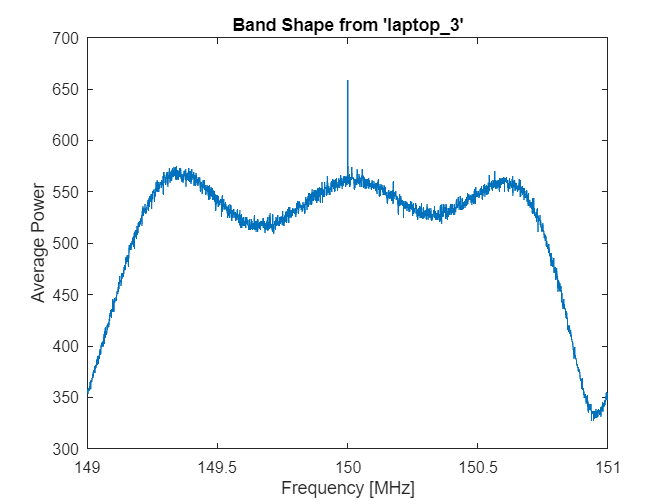

% Import the signal data
num = "3";
filename = "C:\Users\ajdke\OneDrive - Indian Institute of Science\Summer 2022\Project RadTel\GBD\Synchronizing Two RTL-SDRs\Data\samp_on_desktop_"+ num;
desktop = import_signal_data(filename);
filename = "C:\Users\ajdke\OneDrive - Indian Institute of Science\Summer 2022\Project RadTel\GBD\Synchronizing Two RTL-SDRs\Data\samp_on_laptop_" + num;
laptop = import_signal_data(filename);

% Align the signals
laptop = circshift(laptop, finddelay(laptop, desktop));

% Reshape the 1D signals into 2D matrices
laptop = laptop(1 : end - rem(length(laptop), 2048));
laptop = reshape(laptop, [2048, length(laptop) / 2048]);
laptop = laptop';

desktop = desktop(1 : end - rem(length(desktop), 2048));
desktop = reshape(desktop, [2048, length(desktop) / 2048]);
desktop = desktop';

% Fourier Transform the signals
fft_of_laptop = fftshift(fft(laptop, 2048, 2));
power_laptop = abs(fft_of_laptop);
average_power_of_laptop = mean(power_laptop);

fft_of_desktop = fftshift(fft(desktop, 2048, 2));
power_desktop = abs(fft_of_desktop);
average_power_of_desktop = mean(power_desktop);

% Plot the band shapes:
frequency = linspace(149, 151, 2048);

plot(frequency, average_power_of_laptop)
xlabel("Frequency [MHz]")
ylabel("Average Power")
title("Band Shape from 'laptop_" + num + "'", 'Interpreter','none')
saveas(gcf,"Band Shape from 'laptop_" + num + "'",'jpeg')

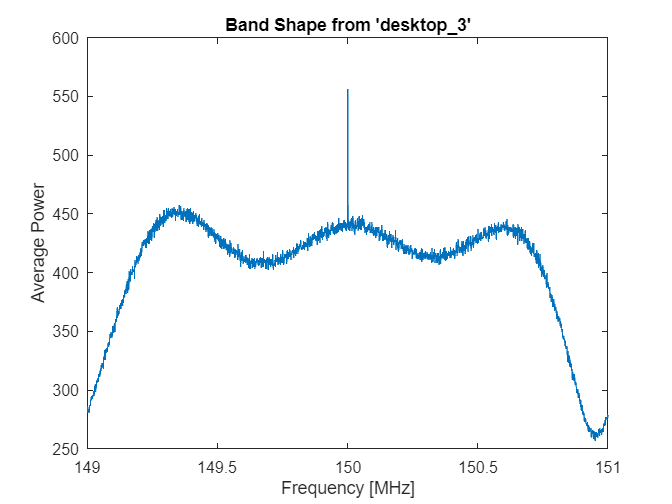


plot(frequency, average_power_of_desktop)
xlabel("Frequency [MHz]")
ylabel("Average Power")
title("Band Shape from 'desktop_" + num + "'", 'Interpreter','none')
saveas(gcf,"Band Shape from 'desktop_" + num + "'",'jpeg')

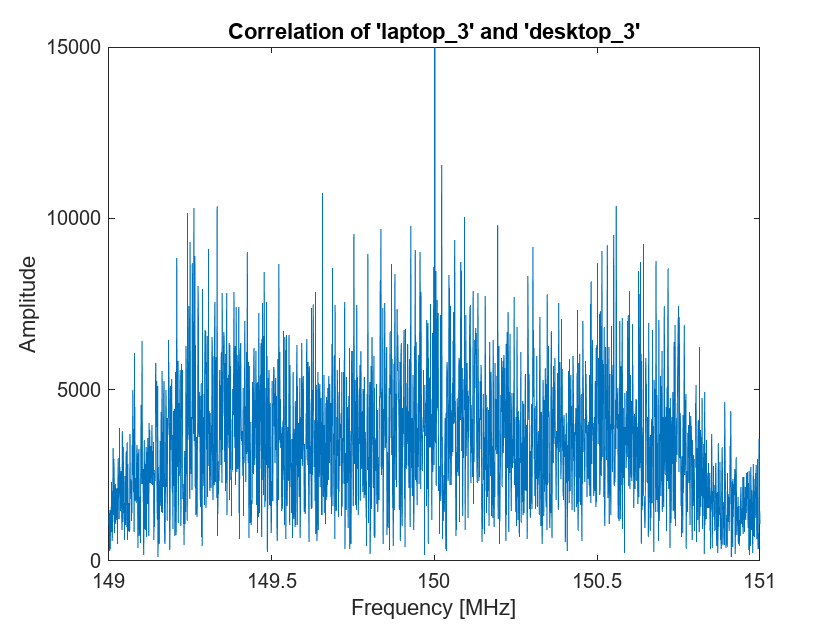


% Correlation Matrix:
complex_corr_matrix = fft_of_laptop .* conj(fft_of_desktop);
avg_complex_corr = mean(complex_corr_matrix);
amplitude = abs(avg_complex_corr);
phase = angle(avg_complex_corr);

% Amplitude and Phase Plots:
plot(frequency, amplitude)
ylim([0,15000])
xlabel("Frequency [MHz]")
ylabel("Amplitude")
title("Correlation of 'laptop_" + num + "' and 'desktop_" + num + "'", 'Interpreter','none')
saveas(gcf,"Amplitude correlation of 'laptop_" + num + "' and 'desktop_" + num + "'",'jpeg')

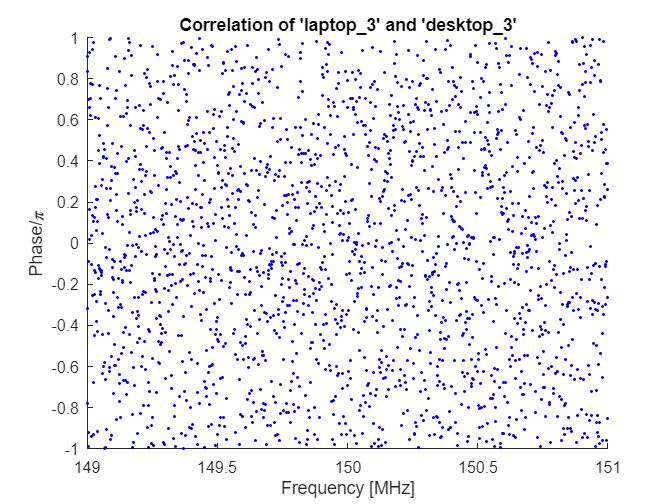


scatter(frequency, phase/pi, 'b.')
xlabel("Frequency [MHz]")
ylabel("Phase/\pi")
title("Correlation of 'laptop_" + num + "' and 'desktop_" + num + "'", 'Interpreter','none')
saveas(gcf,"Phase correlation of 'laptop_" + num + "' and 'desktop_" + num + "'",'jpeg')